fs = 8000;
duration = 0.1;
gap = 0.1;

[~,z] = generate_wave({"1","5","9","D"},fs,duration,gap);

### Low Pass 1 to 4 kHz

signal_low_1 = low_pass1(z,fs);
downsampled_signal_low_1 = downsample(signal_low_1, 2);

### Low Pass 2 to 2 kHz

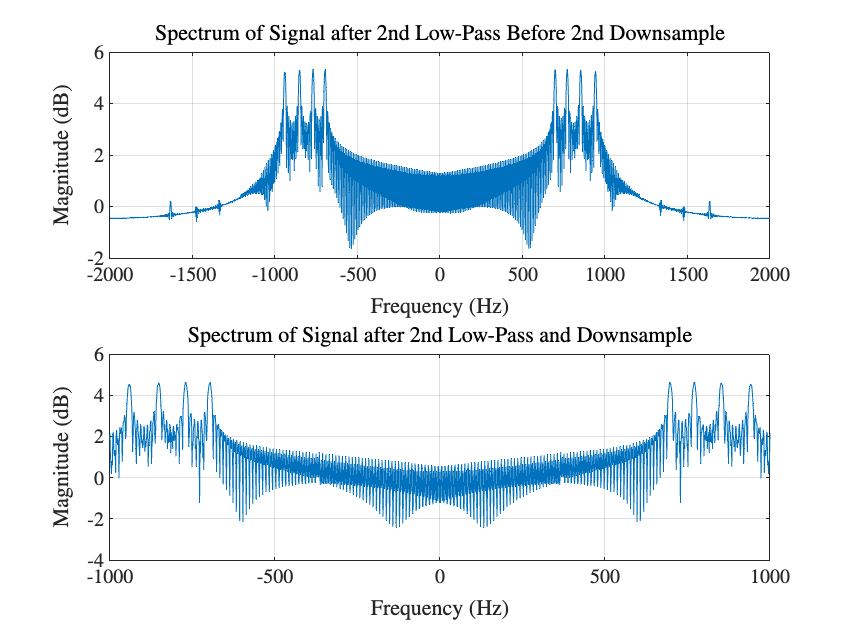

signal_low_2 = low_pass2(downsampled_signal_low_1,fs/2);
downsampled_signal_low_2 = downsample(signal_low_2,2);

low_2_spectrum = fft(signal_low_2);
low_2_downsample_spectrum = fft(downsampled_signal_low_2);

figure()
subplot(2,1,1)
f_output = linspace(-fs/4, fs/4, length(low_2_spectrum));
plot(f_output, log(abs(fftshift(low_2_spectrum))));
grid on
title('Spectrum of Signal after 2nd Low-Pass Before 2nd Downsample');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2,1,2)
f_output = linspace(-fs/8, fs/8, length(low_2_downsample_spectrum));
plot(f_output, log(abs(fftshift(low_2_downsample_spectrum))));
grid on
title('Spectrum of Signal after 2nd Low-Pass and Downsample');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

exportgraphics(gcf, 'TeX/images/4D_LowSpectrumComparison.eps');

### High Pass 2 to 2 kHz

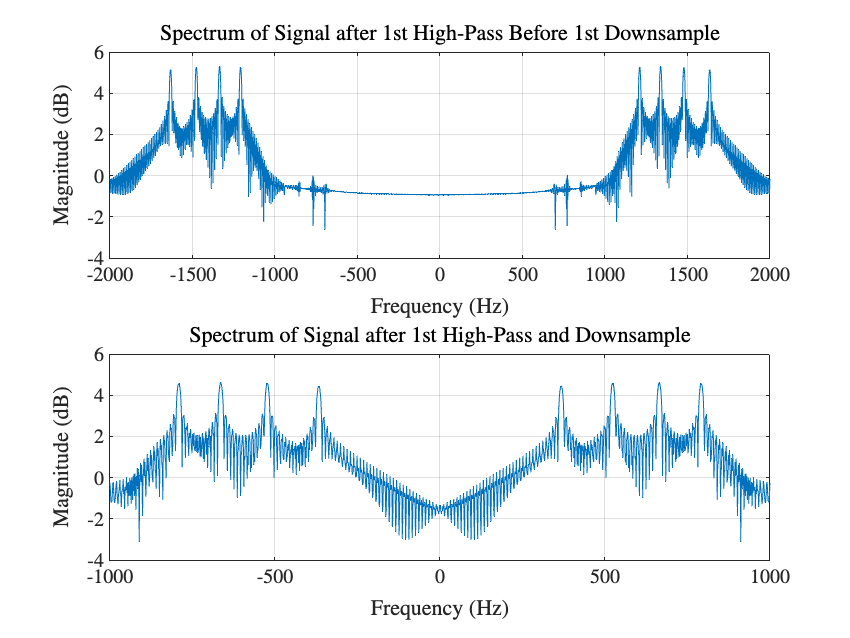

signal_high_2 = high_pass1(downsampled_signal_low_1,fs);
downsampled_signal_high_2 = downsample(signal_high_2,2);

high_2_spectrum = fft(signal_high_2);
high_2_downsample_spectrum = fft(downsampled_signal_high_2);

figure()
subplot(2,1,1)
f_output = linspace(-fs/4, fs/4, length(high_2_spectrum));
plot(f_output, log(abs(fftshift(high_2_spectrum))));
grid on
title('Spectrum of Signal after 1st High-Pass Before 1st Downsample');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2,1,2)
f_output = linspace(-fs/8, fs/8, length(high_2_downsample_spectrum));
plot(f_output, log(abs(fftshift(high_2_downsample_spectrum))));
grid on
title('Spectrum of Signal after 1st High-Pass and Downsample');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

exportgraphics(gcf, 'TeX/images/4D_HighSpectrumComparison.eps');